Based on the results of fitness_chemostat, namely that O2 and NH4 should be increased, and in ancreased upper limit for glc uptake, compare the fitness across varying alphas under such conditions in a 1x1 environment with no media refreshing *and including enzyme decay and cell death*

%%SCRIPT CONTROL VARIABLES
refreshmodel = true;
runalphamodels = true;
runO2models = true;
runNmodels = true;

%%STRATEGY VARIABLES
v.defaultbound = 10; %default exchange upper bound
%v.maxEnzymeRate = 1; %maximum enzyme:biomass ratio by weight for fixed production. 1:1 w/ alpha=1 should mean half of all amino acids go into enzyme
v.alpha = 0.1; %fixed percentage of the maximum enzyme rate being expressed

%%ENZYME VARIABLES. See https://www.brenda-enzymes.org/enzyme.php?ecno=3.2.1.4
%values used: wild-type T.ressei on 4-methylumbelliferyl cellobioside. https://www.brenda-enzymes.org/literature.php?e=3.2.1.4&r=737187
v.kcat_cel = 0.01; %mmol converted / mmol enzyme / second  %TODO: Confirm units
v.km_cel = 0.125; %Units = mmoles/cm^3

%%Glucose variables
v.km_glc = 0.01; %millimoles/cm^3.
v.vmax_glc = 100;
v.glcpercellulose = 218.2;%how many units of glucose get released per unit cellulose? 1:1 assumes units are by weight
    %Avicel degree of polymerization cite : https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3217711/
%v.biomassperglc = 1/(1.447e9); %how many units of biomass are produced for every unit glc consumed?
    %weight of E coli / weight of glc molecule = 433fg / (2.992e-22g) = 4.33e-13 / (2.992e-22) = 1.447e9
v.glcuptakerate = -100; %bound for the GLC import reaction
                         %This should be higher than required for max enzyme production

%%DECAY/DEATH VARIABLES
v.enzdecayperhour = .1;
v.deathrateperh = 0;
                         
%Enzyme variables v 2- set high to check that everything works OK
%v.kat = 100;
%v.km = 0.0001;

%%WORLD/LAYOUT VARIABLES
%v.dilutionrate = 1/24; %fraction of media replaced per hour
v.dilutionrate = 1/12; %fraction of media replaced per hour
v.xdim = 1;
v.ydim = 1;
v.diff_cel = 0; %Diffusion constants
v.diff_enz = 1e-6; %Default is 1e-6;
v.diff_glc = 1e-6;
%v.enzdecayrate = 0; %degradation of enzyme over time
%v.deathrate = 0;
%v.enzymeperglc = 0.05; %how many units of enzyme are produced for every unit glc consumed?
v.initcellulose = 1;
v.initglc = 1e-8; %needed to bootstrap production
v.initmedia = 1; %amount of all other media added
v.initialpop = 1e-3;
v.initO2 = 1000; %oxygen level in the media
v.initNH4 = 1000; %ammonium level in the media

%%COMETS EXECUTION VARIABLES
v.maxcycles = 1000;
v.timestep = 1; %1/(60*60); %1/3600 hours = 1 second. 
v.filepath = 'C:\sync\biomes\cellulose\optima\temp';
v.writemedialog = true;
v.writebiomasslog = true;
v.writefluxlog = false;
v.lograte = 1;
v.maxspacebiomass = 1000;
v.spaceWidth = 10^(1/3);
v.lograte = 1;

v_default = v;

%%DEFAULT MODEL
if refreshmodel
    %model_default = load('C:\sync\biomes\models\ecoli_core_model_norm.mat'); %model with metabolite names normalized
    model_default = load('C:\sync\biomes\models\iJO1366 (1).mat'); %model with metabolite names normalized
    model_default = model_default.iJO1366;
end

alphas = [0.01 0.02 0.05 0.075 0.1 0.15 0.25 0.3 0.4];
%models = cell(length(alphas),1);

ed1models = cell(length(alphas),1);
v.enzdecayperhour = .01;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
    a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=1%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
    ed1models = newmodels;
end


ed2models = cell(length(alphas),1);
v.enzdecayperhour = .02;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=2%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
   ed2models = newmodels;
end


ed3models = cell(length(alphas),1);
v.enzdecayperhour = .03;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=3%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
    ed3models = newmodels;
end


ed4models = cell(length(alphas),1);
v.enzdecayperhour = .04;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=4%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
    ed4models = newmodels;
end

ed5models = cell(length(alphas),1);
v.enzdecayperhour = .05;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=5%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
    ed5models = newmodels;
end

ed6models = cell(length(alphas),1);
v.enzdecayperhour = .06;
v.enzdecaypersec = v.enzdecayperhour / 3600;
tmodels = cell(length(alphas),1);
for i=1:length(alphas)
a = alphas(i);
    v.alpha = a;
    mname = ['a=' num2str(a) ', enzDecay=6%'];
    model = buildEcoliModel(v,model_default,mname,'p');
    tmodels{i} = model;
end
if runalphamodels
    newmodels = cell(length(tmodels),1);
    for i = 1:length(tmodels)
        newmodels{i} = runModel(tmodels{i});
    end
    ed6models = newmodels;
end

models = [ed1models; ed2models; ed3models; ed4models; ed5models; ed6models];

%Plotting
maxbiomasses = zeros(length(alphas),1);
for i = 1 : length(models)
    maxbiomasses(i) = max(models{i}.biomass);
end
maxbiomasses

maxbiomasses =     1.0377
    1.0377
    1.0377
    1.0377
    1.0377
    1.0377
    1.0377
    1.0377
    1.0377
    0.0047


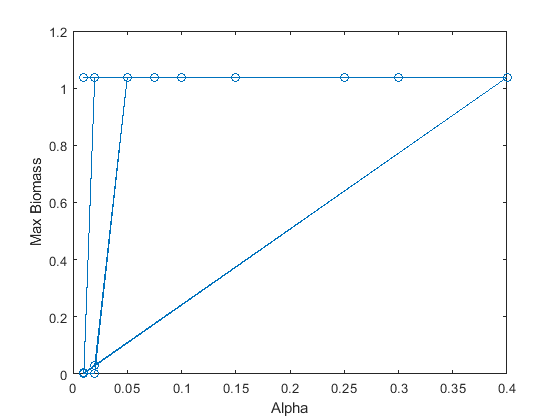

plot([alphas, alphas, alphas, alphas, alphas, alphas],maxbiomasses,'-o');
ylabel('Max Biomass');
xlabel('Alpha');

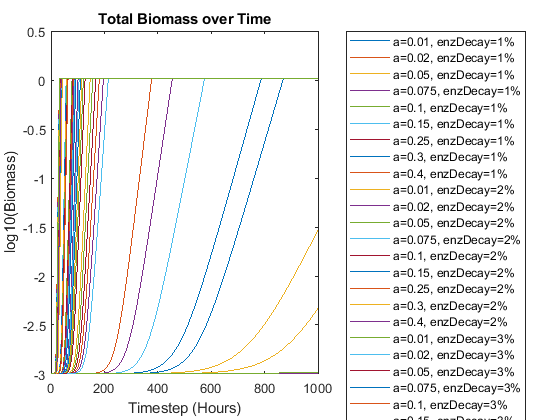

plotBiomassOverTime(models);

%ylim([-4.5 0]);

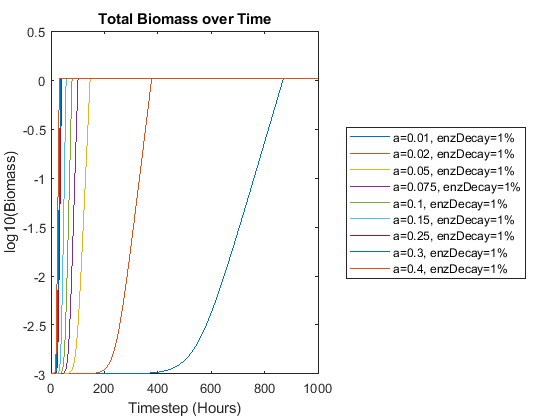

plotBiomassOverTime(ed1models);

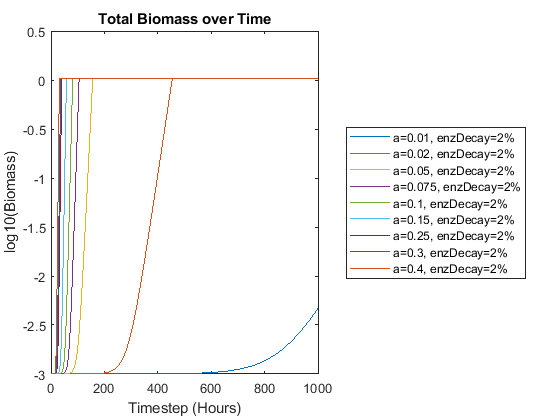

plotBiomassOverTime(ed2models);

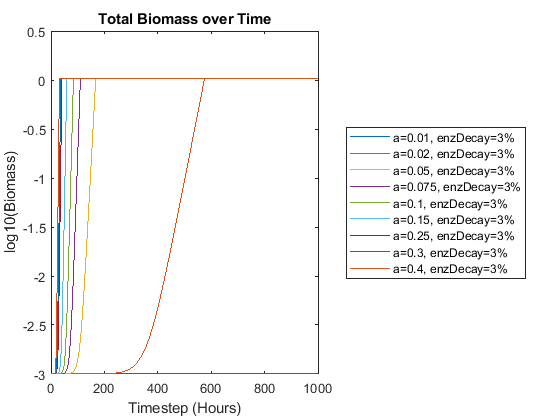

plotBiomassOverTime(ed3models);

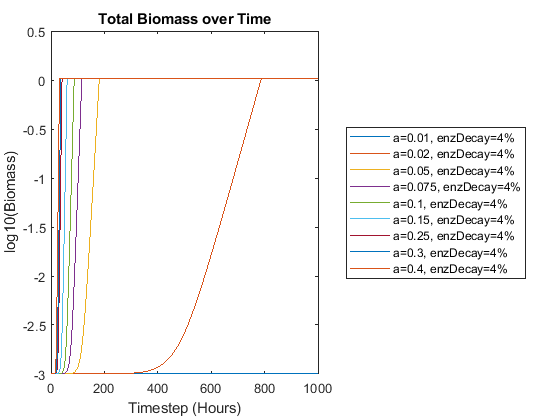

plotBiomassOverTime(ed4models);

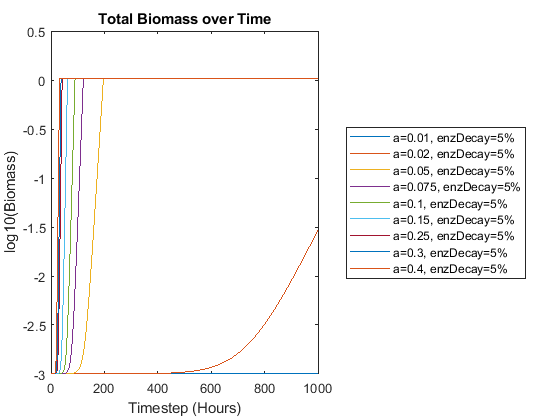

plotBiomassOverTime(ed5models);

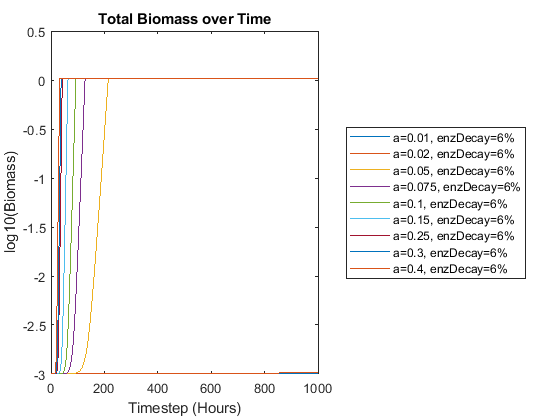

plotBiomassOverTime(ed6models);

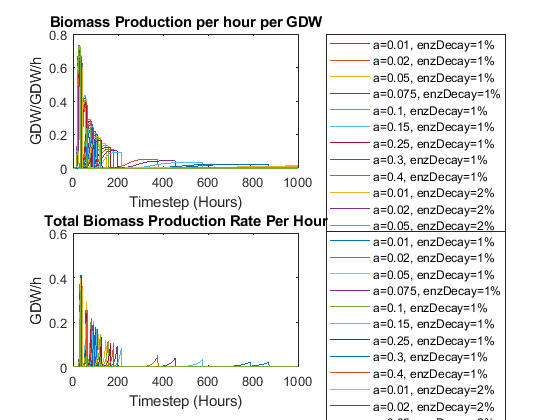

plotGrowthRates(models);

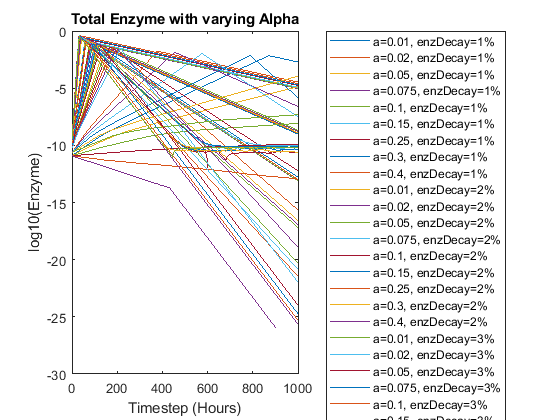

plotEnzymeTimecourse(models);

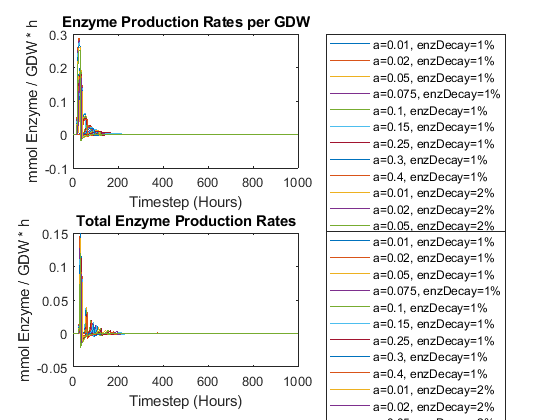

plotEnzRates(models);

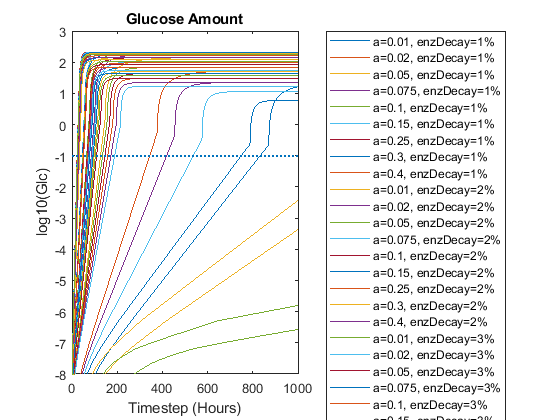

plotGlucoseTimecourse(models);
ylim([-8 3]);

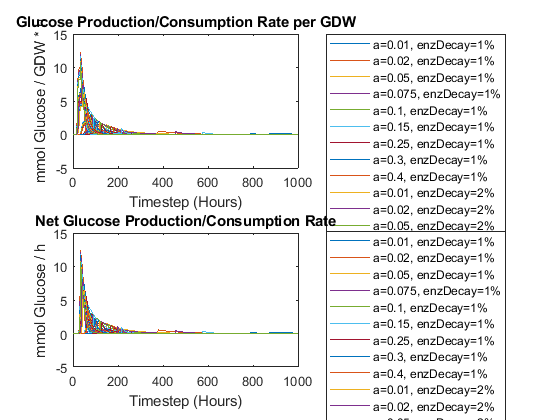

plotGlcRates(models);

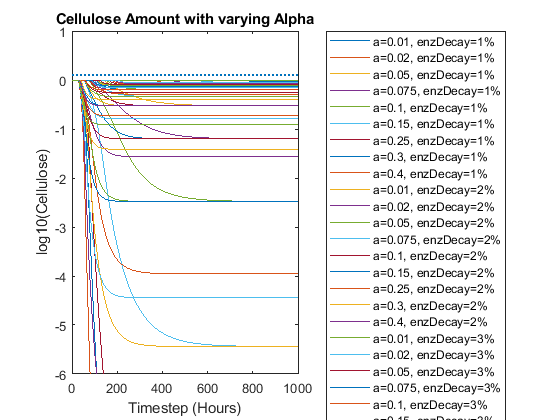

plotCelluloseTimecourse(models);

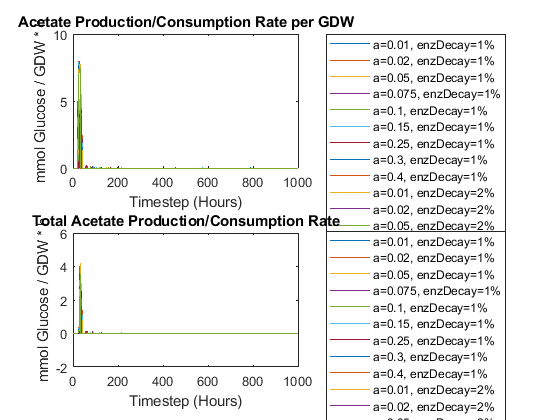

plotAcetateRates(models);

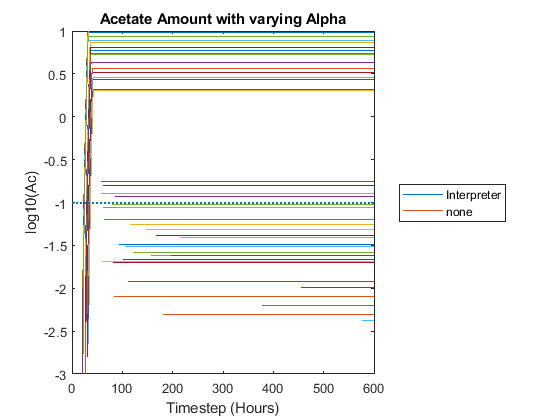

plotAcetateTimecourse(models);
ylim([-3 1])
xlim([0 600])

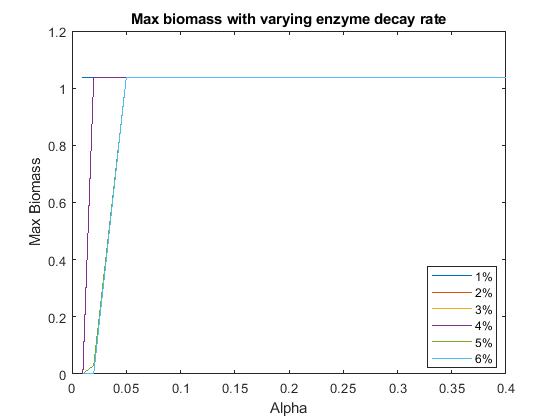


%Make more reasonable graphs with multiple series
m.biomass = zeros(length(alphas),length(models)/length(alphas));
m.biomass(1:end) = maxbiomasses;
plot(alphas,m.biomass(:,1),alphas,m.biomass(:,2),alphas,m.biomass(:,3),alphas,m.biomass(:,4),alphas,m.biomass(:,5),alphas,m.biomass(:,6));
title('Max biomass with varying enzyme decay rate');
xlabel('Alpha');
ylabel('Max Biomass');
leg = legend({'1%' '2%' '3%' '4%' '5%' '6%'},'location','best');

%set(leg,'title','Decay rate per hour');

%Surf plot for alpha / biomass / decayrate
numalphas = length(alphas);
numrates = length(models) / numalphas;
v.maxcycles / v.lograte;
biodat = zeros(numalphas, numrates);
rc = [.01 .02 .03 .04 .05 .06];
for i = 1:length(models)
    model = models{i};
    b = model.biomass;
    a = model.v.alpha;
    biodat(model.v.alpha == alphas, model.v.enzdecayperhour == rc) = max(b);
    %biodat(1:length(rates), model.v.alpha == alphas, model.v.enzdecayperhour == rc,2) = (1:length(rates) * v.timestep) - v.timestep;
    %biodat(1:length(rates), model.v.alpha == alphas, model.v.enzdecayperhour == rc,3) = model.v.alpha;
    
end


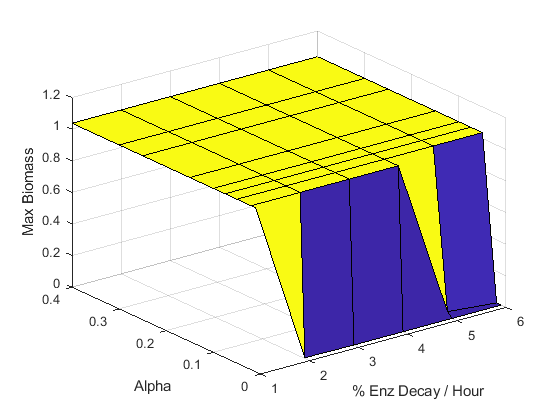

surf(rc*100,alphas,biodat)
xlabel('% Enz Decay / Hour');
ylabel('Alpha');
zlabel('Max Biomass');

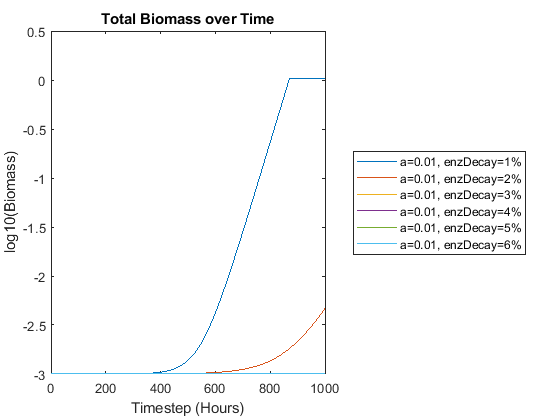

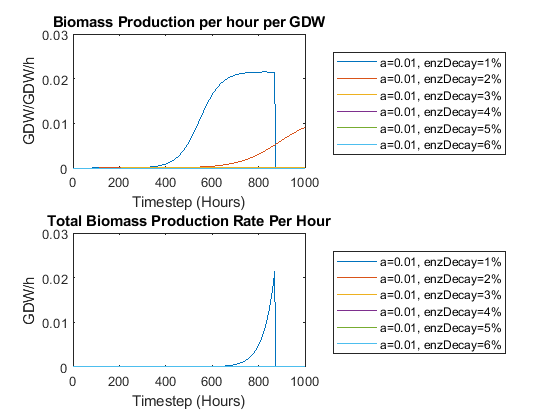

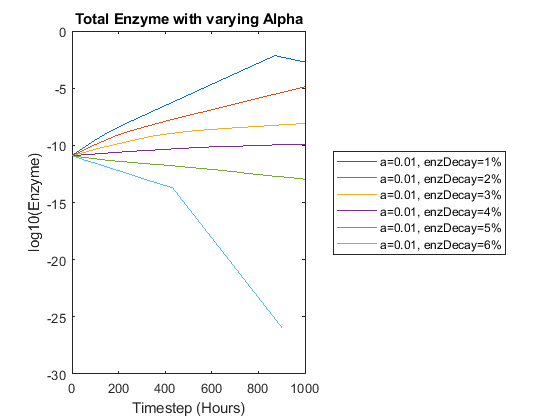

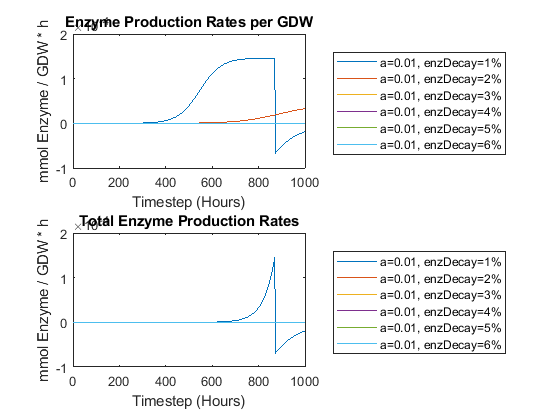

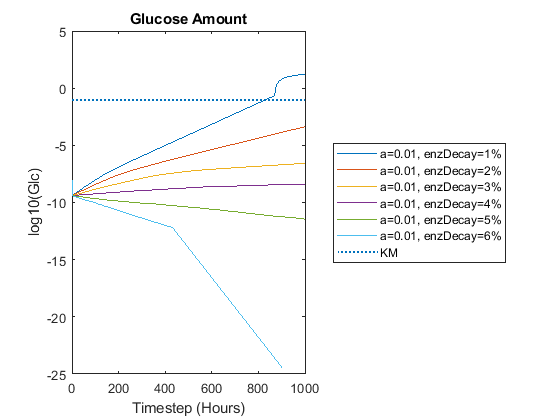

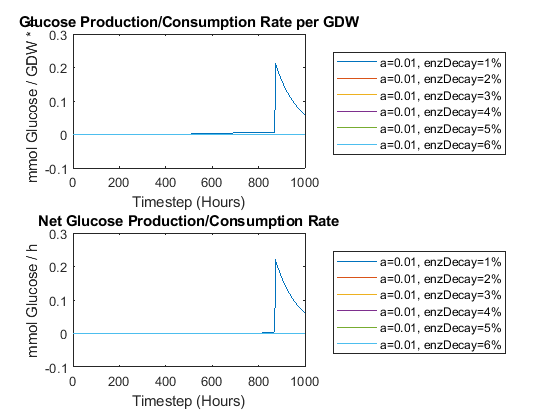

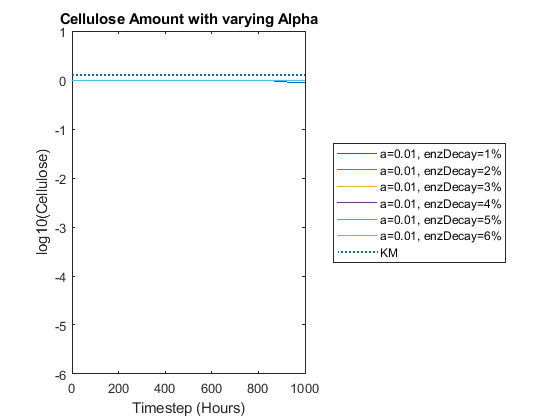

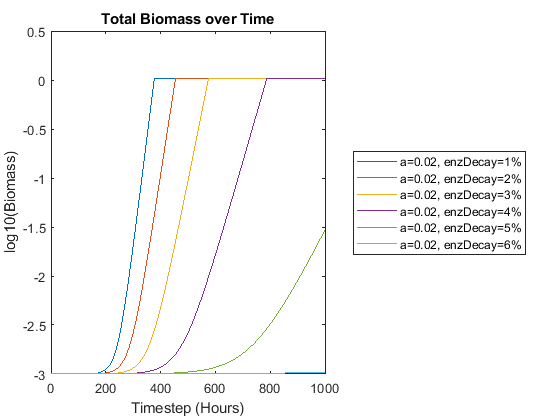

%Group models by Alpha
mm = [ed1models, ed2models, ed3models, ed4models, ed5models, ed6models];
% a1models = mm(1,:);
% a2models = mm(2,:);
% a3models = mm(3,:);
% a4models = mm(4,:);
% a5models = mm(5,:);
% a6models = mm(6,:);
% plotBiomassOverTime(a1models);
% plotBiomassOverTime(a2models); %This appears to be the only point where max biomass is decreased
for i = 1:length(alphas)
    ams = mm(i,:);
    plotBiomassOverTime(ams);
    plotGrowthRates(ams);
    plotEnzymeTimecourse(ams);
    plotEnzRates(ams);
    plotGlucoseTimecourse(ams);
    plotGlcRates(ams);
    plotCelluloseTimecourse(ams);
end

for i = 1:length(alphas)
    plotGlucoseTimecourse(mm(i,:));
end

function model = runModel(model)
model.v.enzdecaypersec = model.v.enzdecayperhour / 3600;
model.v.deathrate = model.v.deathrateperh;

layout = buildCelOptLayout(model);
layout = setMedia(layout,'o2_e',model.v.initO2);
layout = setMedia(layout,'nh4_e',model.v.initNH4);

createCometsFiles(layout,model.v.filepath,'layout_temp.txt');
runCometsOnDirectory(model.v.filepath);

tab = parseBiomassLog([model.v.filepath '\log_biomass.m']);
model.biomass = tab.biomass; %no need to sum if there's no biomass diffusion
model.timestep = tab.t;

if model.v.writemedialog
    media = parseMediaLog([model.v.filepath '\log_media.m'],{'enzyme_e', 'cellulose', 'glc__D_e', 'ac_e'});
    model.enzyme_amt = zeros(length(model.timestep),1);
    model.cellulose_amt = zeros(length(model.timestep),1);
    model.glc_amt = zeros(length(model.timestep),1);
    model.acetate_amt = zeros(length(model.timestep),1);
    for i = 1:length(model.timestep)
        time = model.timestep(i);
        enzrows = (media.t == time) & strcmp(media.metname,'enzyme_e');
        celrows = (media.t == time) & strcmp(media.metname,'cellulose');
        glcrows = (media.t == time) & strcmp(media.metname,'glc__D_e');
        acrows = (media.t == time) & strcmp(media.metname,'ac_e');
        subtab = media(enzrows,:);
        model.enzyme_amt(i) = sum(subtab.amt);
        subtab = media(celrows,:);
        model.cellulose_amt(i) = sum(subtab.amt);
        subtab = media(glcrows,:);
        model.glc_amt(i) = sum(subtab.amt);
        subtab = media(acrows,:);
        model.acetate_amt(i) = sum(subtab.amt);
    end
end

end